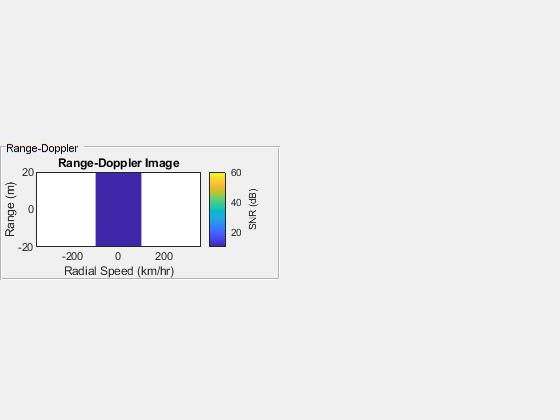

% Add a panel for range doppler plot
hDRPanel = uipanel(figure, 'Position', [0 1/3 1/2 1/3], 'Title', 'Range-Doppler ');
hdrange = axes(hDRPanel);
backLim = -20;
frontLim = 20;
vmax = 100;
% Initialize plot parameters for Range-Doppler response
hi_rng_dopp = imagesc(hdrange,[-50 50],[backLim frontLim], zeros(2,2));
hdrange.YDir = 'normal';
ylim(hdrange,[backLim frontLim])
xlim(hdrange,[-vmax vmax]*3600/1000); % m/s -> km/hr
caxis(hdrange,[10 60])
ylabel(colorbar('peer',hdrange),'SNR (dB)');
xlabel(hdrange,'Radial Speed (km/hr)')
ylabel(hdrange,'Range (m)')
title(hdrange,'Range-Doppler Image')